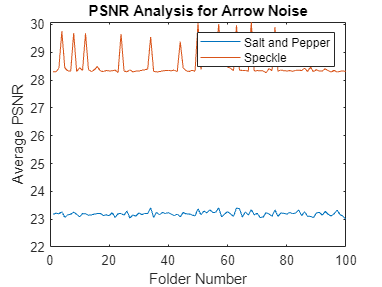

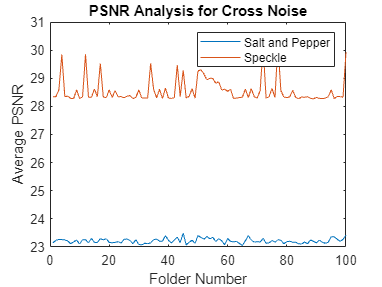

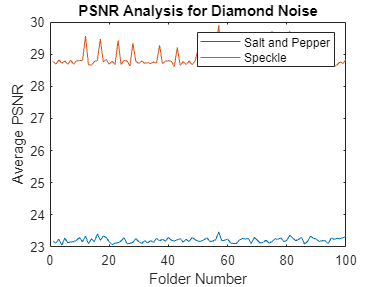

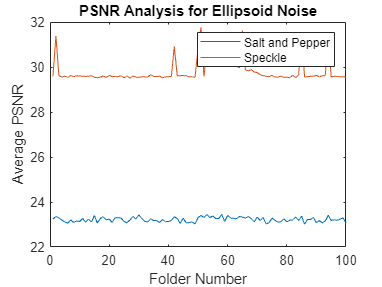

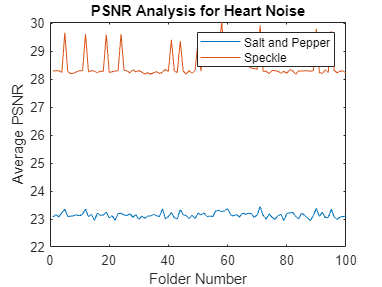

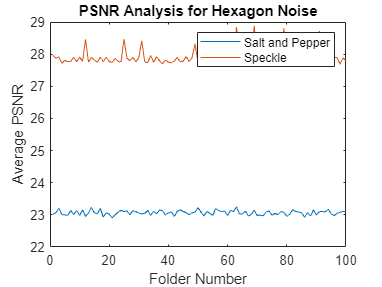

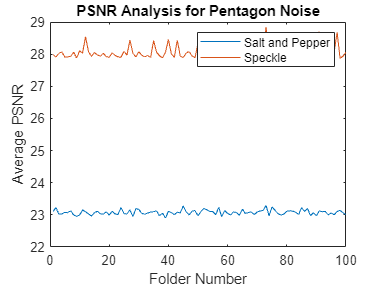

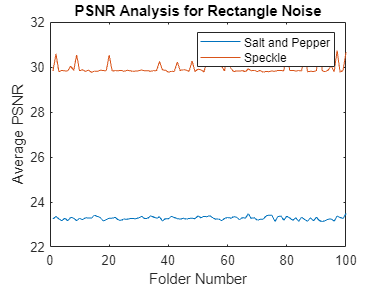

% Set the base directory
base_dir = 'D:\University\Year 4\Project\Simulation\Results\Noisy Images';
original_base_dir = 'D:\University\Year 4\Project\Simulation\Results';
output_dir = 'D:\University\Year 4\Project\Simulation\SNR';

% Get the list of shape-named folders
shape_folders = dir(base_dir);
shape_folders = shape_folders([shape_folders.isdir] & ~strcmp({shape_folders.name},'.') & ~strcmp({shape_folders.name},'..'));

% Loop through each shape-named folder
for shape_idx = 1:length(shape_folders)
    shape_folder = fullfile(base_dir, shape_folders(shape_idx).name);
    original_shape_folder = fullfile(original_base_dir, shape_folders(shape_idx).name);

    % Get the list of 2 subfolders in the shape-named folder
    subfolders = dir(shape_folder);
    subfolders = subfolders([subfolders.isdir] & ~strcmp({subfolders.name},'.') & ~strcmp({subfolders.name},'..'));

    % Initialize the average SNR array for 100 folders in each subfolder
    avg_snr_all = [];

    % Loop through each subfolder
    for sub_idx = 1:length(subfolders)
        subfolder = fullfile(shape_folder, subfolders(sub_idx).name);
        original_subfolder = fullfile(original_shape_folder, subfolders(sub_idx).name);

        % Get the list of 100 folders in the subfolder
        folders = dir(subfolder);
        folders = folders([folders.isdir] & ~strcmp({folders.name},'.') & ~strcmp({folders.name},'..'));
        
        % Initialize the average SNR array for the 100 folders
        avg_snr = [];
        
        % Loop through each of the 100 folders
        for folder_idx = 1:length(folders)
            folder = fullfile(subfolder, folders(folder_idx).name);
            original_folder = strrep(folders(folder_idx).name, '_speckle', '');
            original_folder = strrep(original_folder, '_saltnpepper', '');
            original_shape_folder_no_noise = strrep(original_shape_folder, ' Noise', ''); % Remove ' Noise' from original_shape_folder
            original_folder = fullfile(original_shape_folder_no_noise, original_folder);


            % Get the list of 16 noisy images in the folder
            image_files = dir(fullfile(folder, '*.jpg')); % Change the extension if the images have a different format
            original_image_files = dir(fullfile(original_folder, '*.jpg'));

            % Initialize the SNR array for the 16 images
            snr_values = [];

            % Loop through each of the 16 images
            if length(image_files) == length(original_image_files)
                for img_idx = 1:length(image_files)
                    img_file = fullfile(folder, image_files(img_idx).name);
                    original_img_file = fullfile(original_folder, original_image_files(img_idx).name);
                    img = imread(img_file);
                    original_img = imread(original_img_file);
            
                    % Calculate the PSNR of the image
                    psnr_value = calc_psnr(original_img, img);
                    snr_values = [snr_values, psnr_value];
                end
            else
                error(['The number of images in the noisy folder (' folder ') does not match the number in the original folder (' original_folder ').']);
            end

            % Calculate the average SNR of the 16 images
            avg_snr_folder = mean(snr_values);
            avg_snr = [avg_snr, avg_snr_folder];
        end

        % Store the average SNR for the 100 folders
        avg_snr_all = [avg_snr_all; avg_snr];
    end

    % Create a graph plotting the average SNR of the 100 folders
    figure;
    plot(1:100, avg_snr_all(1,:), 1:100, avg_snr_all(2,:));
    legend(subfolders(1).name, subfolders(2).name);
    xlabel('Folder Number');
    ylabel('Average PSNR');
    title(['PSNR Analysis for ', shape_folders(shape_idx).name]);
    saveas(gcf, fullfile(output_dir, [shape_folders(shape_idx).name, '_PSNR_Analysis.png']));
end

function psnr_value = calc_psnr(original_img, noisy_img)
    % Convert images to double precision
    original_img = double(original_img);
    noisy_img = double(noisy_img);
    
    % Calculate the Mean Squared Error (MSE) between the original and noisy images
    mse = mean((original_img(:) - noisy_img(:)) .^ 2);
    
    % Calculate the maximum possible pixel value of the image (assuming 8-bit image)
    max_pixel_value = 255;
    
    % Calculate the PSNR value
    if mse == 0
        psnr_value = Inf;
    else
        psnr_value = 20 * log10(max_pixel_value / sqrt(mse));
    end
end